## Data Input


close all;
clear all;
colors=npg(10); % Ten basic colors 
%% 对比度
%maindir='\\Artemis-pc\Data\2026-05-18\Abs-101\';   % 对比度
%load([maindir,'\FitResult.mat']);
%% 相位
maindir='\\Artemis-pc\Data\2026-05-15\Abs-452\';
load([maindir,'diffR.mat'])
%load([maindir,'\population.mat']);
%load([maindir,'\result.mat']);


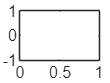


time_interval = 15+0;   % s

sz = p173;
%sz = (s3-s4)./(s3+s4)/amp;
%sz([1:10]) = [];
lensz = length(sz);
figure;
plot(1:lensz,sz,'.');
set(gca,'YLim',[-1 1]);

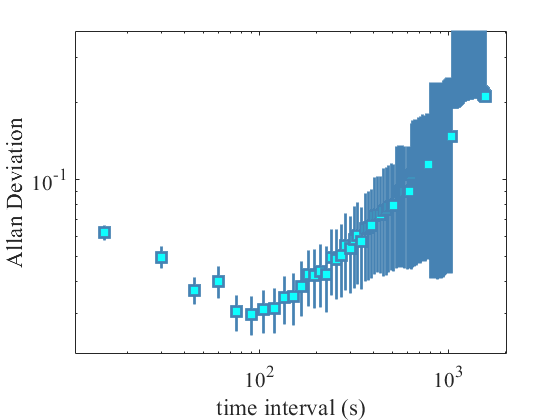

maxaver = floor(lensz/2);

tlist = (1:maxaver)*time_interval;

for avernum = 1:maxaver   % 一次平均的数据总数
    dsz = 0;
    n_div(avernum) = floor(lensz/avernum)-1;   % 平均值做差的次数
    for k = 1:n_div(avernum)
        sz1 = mean(sz((k-1)*avernum+1:k*avernum));
        sz2 = mean(sz(k*avernum+1:(k+1)*avernum));
        dsz(k) = (sz2-sz1)^2;
    end
    allan_dsz(avernum) = sqrt(mean(dsz)/2);
    allan_std(avernum) = allan_dsz(avernum)/sqrt(n_div(avernum));
    %allan_std(avernum) = 1/sqrt(2*mean(dsz))*std(dsz)/sqrt(n_div(avernum)-1);
end

[allan_d,allan_s] = allanvar(sz);

f1 = figure; hold on;

l1 = plot(tlist,allan_dsz,'square');
set(l1,'Color',[0.274 0.51 0.7],'MarkerFaceColor',[0.36 0.93 0.93],...
    'LineWidth',2,'MarkerSize',10);
e1 = errorbar(tlist,allan_dsz,allan_std,'square');
set(e1,'Color',[0.274 0.51 0.7],'MarkerFaceColor',[0.059 1 1],...
    'CapSize',0,'LineWidth',2,'MarkerSize',10);
% e1 = errorbar(1:length(allan_d),allan_d,allan_s,'square');
% set(e1,'Color',[0.274 0.51 0.7],'MarkerFaceColor',[0.059 1 1],...
%     'CapSize',0,'LineWidth',2,'MarkerSize',13);
box on;

set(gca,'XScale','log','YScale','log',...
    'FontName','times new roman','FontSize',16);
xlabel('time interval (s)');
ylabel('Allan Deviation');
xlim([time_interval*0.7 maxaver*time_interval*1.3]);
ylim([min(allan_dsz)*0.7 max(allan_dsz)*1.7]);

set(f1,'Visible','on');


save([maindir,'allan.mat']);

saveas(f1,[maindir,'allan.png']);

savefig(f1,[maindir,'allan.fig']);
